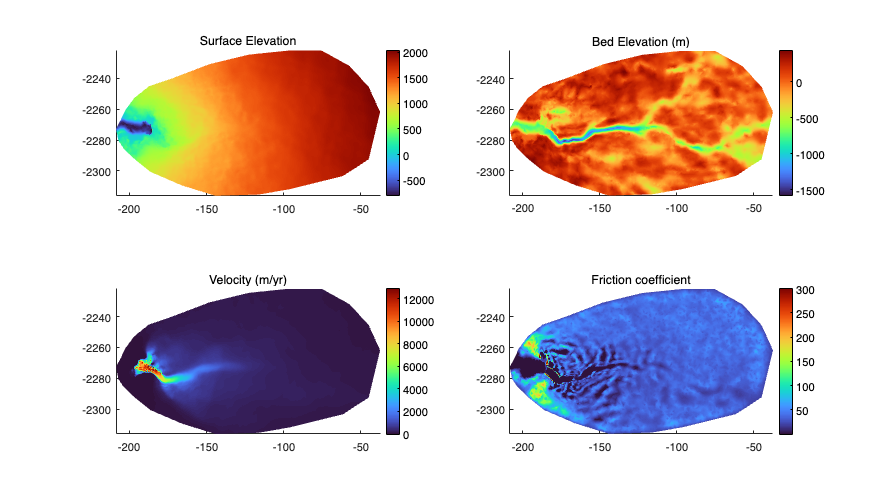

% Load the inversion model of Jakobshavn Isbrae and plot some result parameters
md=loadmodel('/Users/rishi/Desktop/ISSM/examples/Jakobshavn/Jakob_inversion');

plotmodel(md,'data',md.geometry.surface,'title','Surface Elevation',...
'data',md.geometry.base,'title','Bed Elevation (m)',...
'data',md.initialization.vel,'title','Velocity (m/yr)',...
'data',md.friction.coefficient,'title','Friction coefficient',...
'unit#all','km','figposition','fullscreen')

## Select the year window for the Transient simulation

initialtime = 2014;
finaltime   = 2016;

## Import the mass balance data for Transient simulation

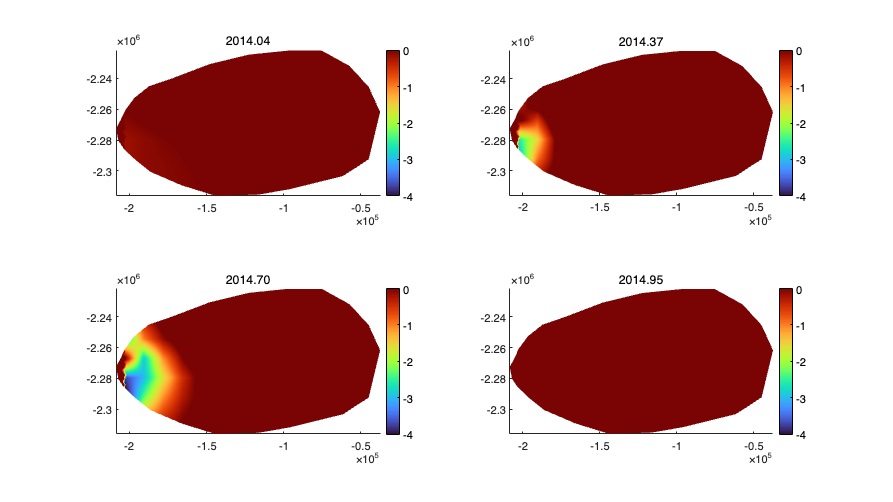

% Read the SMB file and process the data (Coordinates and time)
filename = '/Users/rishi/Desktop/ISSM/examples/data/SMB_Greenland_NASA_GFSC.nc';
x = double(ncread(filename,'x')); % in meters
y = double(ncread(filename,'y')); % in meters
SMB = double(ncread(filename,'SMB')); % already in meters ice equivalent per year
SMB(SMB == -9999) = NaN; %replace missing values with nan
time = ncread(filename,'time');
dt = datetime(1980,1,1):days(5):datetime(2022,6,25); % same as the date matrix
years = unique(year(dt)); % get the years from the data

%--------------------------------------------------------------------------
% We want to interpolate the mass balance data in monthly interval to force
% ISSM for the transient simulation
%--------------------------------------------------------------------------
% mask timesteps for chosen years
in_window = year(dt) >= initialtime & year(dt) <= finaltime;
dt_window = dt(in_window);
SMB_window = SMB(:,:,in_window);
% Group by months 
[year_vec, month_vec, ~] = ymd(dt_window);
% unique (year, month) combinations
[unique_months, ~, month_idx] = unique(year_vec*100 + month_vec); 
n_months = numel(unique_months);

% allocate ISSM SMB forcing array
md.smb.mass_balance = zeros(md.mesh.numberofvertices + 1, n_months);
% store decimal year of the midpoint of each month
for m = 1:n_months
    % all 5-day slices belonging to this year-month and average them
    slices = (month_idx == m);
    this_month = mean(SMB_window(:,:,slices), 3, 'omitnan');
    % interpolate to mesh
    md.smb.mass_balance(1:end-1,m) = ...
        InterpFromGridToMesh(x, y, this_month, md.mesh.x, md.mesh.y, 0);
    % timestamp = mid of the month
    y_m = floor(unique_months(m)/100);
    m_m = mod(unique_months(m),100);
    mid_month = datetime(y_m, m_m, 15); % approx mid-month
    md.smb.mass_balance(end,m) = year(mid_month) + (day(mid_month,'dayofyear')-1)/365.0;
end

% replace NaNs with zeros for stability
md.smb.mass_balance(isnan(md.smb.mass_balance)) = 0;
clearvars -except md initialtime finaltime % remove all the unnecessary variables

% check the data
plotmodel(md,'figposition','fullscreen',...
'data',md.smb.mass_balance(1:end-1,1), ...
'title',num2str(md.smb.mass_balance(end,1),'%.2f'),...
'data',md.smb.mass_balance(1:end-1,5), ...
'title',num2str(md.smb.mass_balance(end,5),'%.2f'),...
'data',md.smb.mass_balance(1:end-1,9), ...
'title',num2str(md.smb.mass_balance(end,9),'%.2f'),...
'data',md.smb.mass_balance(1:end-1,12), ...
'title',num2str(md.smb.mass_balance(end,12),'%.2f'), ...
'caxis#all',[-4 0])

## Step 2: Set Time-Dependent Ice Front Position

md.initialization.pressure = zeros(md.mesh.numberofvertices,1);

% spc thickness on the boundary
md.masstransport.spcthickness = NaN(md.mesh.numberofvertices,1); % Dirichlet boundary condition for thickness
pos=find((md.mask.ice_levelset<0).*(md.mesh.vertexonboundary)); % find vertices that are inside ice
md.masstransport.spcthickness(pos) = md.geometry.thickness(pos); % force the thickness = current geometry thickness

% Set parameters
md.inversion.iscontrol=0;                   % Switch off control/inversion mode 
md.timestepping.start_time = initialtime;   % Starting time for transient simulation
md.timestepping.time_step = 0.01;           % Time step = 0.05 years (~18 days)
md.timestepping.final_time = finaltime;     % End time of the transient simulation
md.settings.output_frequency = 10;          % Only save results every 10 timesteps (to reduce file size)
md.transient.ismovingfront=1;               % Calving front will evolve - switched on
md.transient.isslc = 0;                     % No sea level change coupling.
md.transient.isthermal=0;                   % Ignore heat equation (no thermal evolution)
md.transient.isstressbalance=1;             % Solve ice stresses
md.transient.ismasstransport=1;             % Solve ice thickness/mass balance.
md.transient.isgroundingline=1;             % Allow grounding line migration
md.groundingline.migration = 'SubelementMigration'; % Use subelement grounding line migration scheme (more accurate)

% spclevelset
disp('Assigning Calving front');

Assigning Calving front



% Reset the ice mask: initial condition is from the geometry
pos=find(md.mask.ice_levelset<0); md.mask.ice_levelset(pos)=-1; % Ice-covered cells
pos=find(md.mask.ice_levelset>0); md.mask.ice_levelset(pos)=+1; % Non-ice cells

% get observed calving front from Greene’s dataset, 1972–2022
mask = interpMonthlyIceMaskGreene(md.mesh.x, md.mesh.y, ...
[md.timestepping.start_time, md.timestepping.final_time], 1, ...
'/Users/rishi/Desktop/ISSM/examples/Data/greenland_ice_masks_1972-2022_v1.nc');

% convert icemask to levelset distance
distance = zeros(size(mask));
for i = 1:size(mask,2)
    distance(1:end-1,i) = reinitializelevelset(md, mask(1:end-1,i));
end
distance(end,:) = mask(end,:);

% transient spc
md.levelset.spclevelset = distance; % spclevelset forces the front to match observed positions at given times
disp(['Load observed calving front: ', num2str(size(md.levelset.spclevelset,2)), ...
' records from ', datestr(md.levelset.spclevelset(end,1)*365.25, 'yyyy-mm-dd'), ' to ',...
datestr(md.levelset.spclevelset(end,end)*365.25, 'yyyy-mm-dd')]);

Load observed calving front: 26 records from 2013-12-28 to 2016-01-28


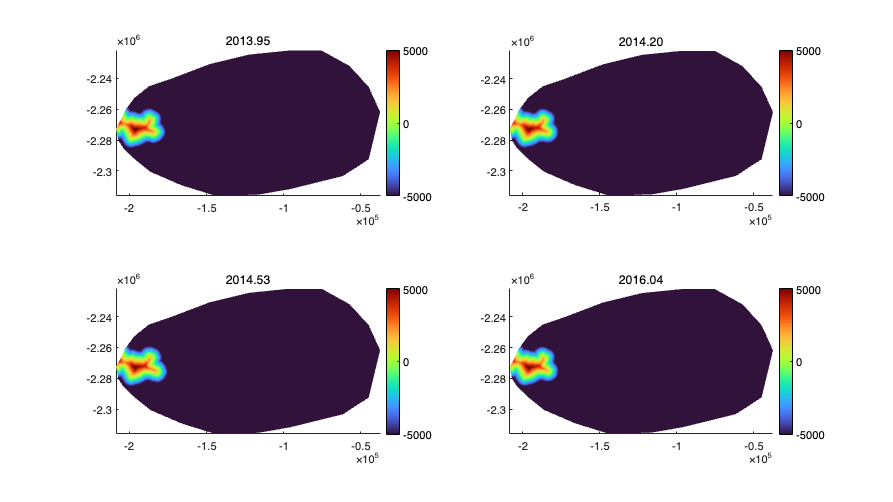


% Plot the fronts
plotmodel(md, ...
'data', md.levelset.spclevelset(1:end-1,1), ...
'title',num2str(md.levelset.spclevelset(end,1),'%.2f'),...
'data',md.levelset.spclevelset(1:end-1,4),...
'title',num2str(md.levelset.spclevelset(end,4),'%.2f'),...
'data',md.levelset.spclevelset(1:end-1,8),...
'title',num2str(md.levelset.spclevelset(end,8),'%.2f'),...
'data',md.levelset.spclevelset(1:end-1,end),...
'title',num2str(md.levelset.spclevelset(end,end),'%.2f'),...
'caxis#all',[-0.5e4,0.5e4])

## Calving simulation

pos = find(md.geometry.base<md.geometry.bed);
md.geometry.base(pos) = md.geometry.bed(pos);
pos = find(md.mask.ice_levelset<0);
md.geometry.base(pos) = md.geometry.bed(pos);
md.geometry.thickness = md.geometry.surface - md.geometry.base;

% calving parameters
md.calving = calving();
md.calving.calvingrate = zeros(md.mesh.numberofvertices+1,1);

% meltingrate
md.frontalforcings.meltingrate=zeros(md.mesh.numberofvertices+1,1);
md.verbose.solution = 1;
md.miscellaneous.name = 'jakob_calvingobs';
md.transient.requested_outputs={'default','IceVolume','IceVolumeAboveFloatation','MaskOceanLevelset','MaskIceLevelset'};
md=solve(md,'Transient');

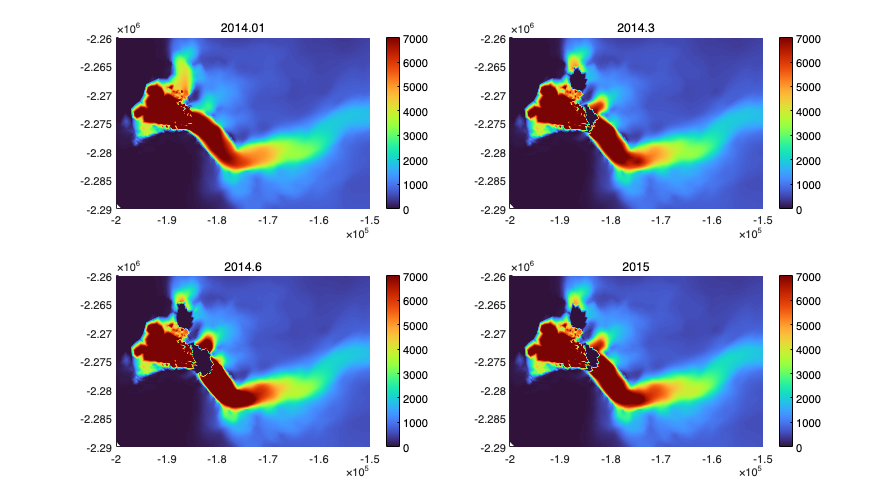

% Plot the results of the calving simulation
plotmodel(md, 'figposition','fullscreen',...
'caxis#all',[0,7e3],'axis#all',[-2e5,-1.5e5,-2.29e6,-2.26e6],...
'data', md.results.TransientSolution(1).Vel,...
'title', num2str(md.results.TransientSolution(1).time),...
'data', md.results.TransientSolution(4).Vel,...
'title', num2str(md.results.TransientSolution(4).time),...
'data', md.results.TransientSolution(7).Vel,...
'title', num2str(md.results.TransientSolution(7).time),...
'data', md.results.TransientSolution(11).Vel,...
'title', num2str(md.results.TransientSolution(11).time))